%Inputs
clc
clear
%Inputs
clc
clear

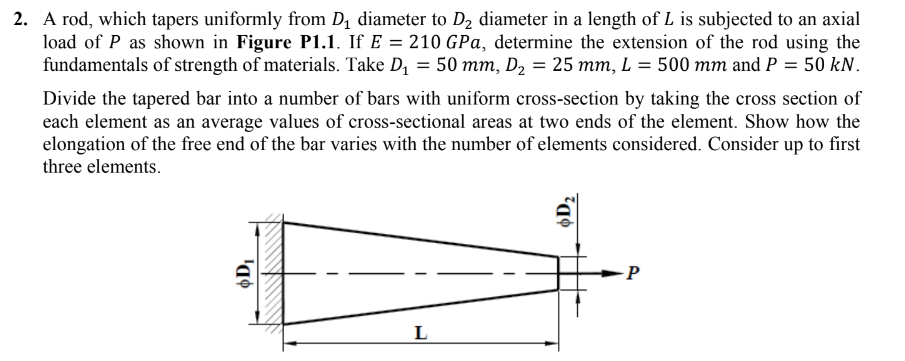

format shortE
L=400

L =    400


E=200e3

E =       200000


E in N/mm^2, L in mm

P=40e3

P =        40000


Exact Value Calculation:

ev= 2*atan(L/150)*P/(3*E)

ev =    1.6160e-01


Input the number of elements for finding the deflection using FEM

n=input("Enter the number of elements: ")

n =      3


Loop for finding the value of x,H and A required for each element

for m=1:1+n
    x(m)=(m-1)*L/n;
   
end

Area average

for i=1:n
    xav(i)=(x(i)+x(i+1))/2;
     A(i)=225+0.01*(xav(i))^2;
end

Taking initial deformation =0 mm and taking average of area at two ends for area of the element, we have,


for m=1:n
    td(m)=P*(L/n)/(E*A(m))
end 

td =    9.8969e-02


td =    9.8969e-02   4.2667e-02


td =    9.8969e-02   4.2667e-02   1.9958e-02


total=sum(td)

total =    1.6159e-01


Calculation of error percentage

error_percentage=abs(total-ev)*100/ev

error_percentage =    5.7314e-03


fprintf("The total deformation is %.15f ",total;

The total deformation is 0.098969072164948 The total deformation is 0.042666666666667 The total deformation is 0.019958419958420 

fprintf("The percentage error is %f",error_percentage);

The percentage error is 0.005731

disp(error_percentage);

   5.7314e-03

